clear;clc;

origState = rng(17);
msg = randi([0 1],800,1);
%Generate complex signals
cfg4a = lrwpanHRPConfig( ...
    Mode='802.15.4a', ...
    MeanPRF=15.6, ...
    Channel=3, ...
    CodeIndex=6, ...
    PSDULength=length(msg)/8) %#ok<NOPTS>

cfg4a =   lrwpanHRPConfig - 属性:

             Channel: 3
                Mode: '802.15.4a'
             MeanPRF: 15.6000
            DataRate: 0.8500
     SamplesPerPulse: 4
           CodeIndex: 6
     PreambleMeanPRF: 16.1000
    PreambleDuration: 64
             Ranging: 0
          PSDULength: 100

   Read-only properties:
          SampleRate: 1.9968e+09


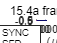

wave4a = lrwpanWaveformGenerator(msg,cfg4a);
%Note: It is a baseband signal.
lrwpanPlotFrame(wave4a,cfg4a);

%HPRF has configuration of samplesPerPulse

info(cfg4a ...
    )

ans = 包含以下字段的 struct :
                    PeakPRF: 499.2000
            BurstsPerSymbol: 32
               NumHopBursts: 8
              ChipsPerBurst: 16
             ChipsPerSymbol: 512
        ConvolutionalCoding: 1
         PreambleCodeLength: 31
    PreambleSpreadingFactor: 16



indices = lrwpanHRPFieldIndices(cfg4a); % length (start/end) of each field
preamble = wave4a( ...
    1:indices.SYNC(end)/cfg4a.PreambleDuration); % 1 of the Nsync repetitions
% plot(preamble)


%这是调制后的载波
channelSpec = [3 4992.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #3: Center frequency = 4992.8 MHz, Bandwidth = 499.2 MHz.


% 旋转函数
function rotated_points = rotate_points(points, angle, center)
    theta = deg2rad(angle);
    rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated_points = (rotation_matrix * (points' - center') + center')';
end

function [peaksChosen,peaksChosenValue]=findMPC(cir)
    [peaksValue,peaksIdx]=findpeaks(cir);
    %设置阈值
    threshold=0.5*max(abs(cir));
    %找到所有在阈值之上的峰，需要记录峰的索引和峰值
    peaksChosen=peaksIdx(peaksValue>threshold);
    peaksChosenValue=peaksValue(peaksValue>threshold);
end


function cross_corr=CalculateXCorr(preamble,signal)
    % 计算信号的长度
    len1 = length(preamble);
    len2 = length(signal);
    
    % 扩展信号1和信号2，使其长度相等
    maxLen = max(len1, len2);
    signal1 = [preamble; zeros(maxLen - len1,1)];
    signal2 = [signal; zeros(maxLen - len2,1)];
    
    % 对信号1取复共轭
    signal1=flipud(signal1);
    signal2_conj = conj(signal2);
    
    % 计算互相关操作
    cross_corr = ifft(fft(signal2_conj) .* fft(signal1));
end


function adjusted_array = adjust_to_range(array)
    adjusted_array = array;
    for i = 1:numel(array)
        while adjusted_array(i) > pi
            adjusted_array(i) = adjusted_array(i) - 2*pi;
        end
        while adjusted_array(i) < -pi
            adjusted_array(i) = adjusted_array(i) + 2*pi;
        end
    end
end

% 定义接收位置和对应的测量误差
errors=[];
TXs=[];

% 定义墙面特性
wall1_position = [5, 0]; % 墙面1位置
wall2_position = [0, 5]; % 墙面2位置
reflection_coefficient = 0.8; % 反射系数

% 定义天线特性
tx_antenna_gain = 2; % 发射天线增益为 2 dB
rx_antenna_gain = 2; % 接收天线增益为 2 dB

% 配置天线阵列
tx_array_length = 3;
rx_array_length = 3;
c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/4992.8e6;
antennaSpacing = lambda / 2;
tx_array_spacing = antennaSpacing;
rx_array_spacing = antennaSpacing;
tx_array_angle = 135; % 发射端天线阵列与水平轴夹角
rx_array_angle = 135; % 接收端天线阵列与水平轴夹角

% 定义天线位置
rx_position = [0, 0]; 

%UWB的频率和采样率
frequency=4992.8e6;
fs=cfg4a.SampleRate;

%遍历tag的位置
% tx_position = [15, 15]; 

for x=8:15
    for y=8:15
        tx_position=[x,y];
        % 计算天线阵列位置
        tx_array_positions = [tx_position-[tx_array_spacing,0];tx_position;tx_position+[tx_array_spacing,0]];
        rx_array_positions = [rx_position-[rx_array_spacing,0];rx_position;rx_position+[rx_array_spacing,0]];
        
        
        % 将天线阵列位置进行旋转
        tx_array_positions = rotate_points(tx_array_positions, tx_array_angle, tx_position);
        rx_array_positions = rotate_points(rx_array_positions, rx_array_angle, rx_position);
        
        
        % 计算锚点到标签的向量
        vecAnchorToTag = rx_position-tx_position;
        
        


        % 计算锚点到标签的向量
        vecAnchorToTag = rx_position - tx_position;
        
        % 计算向量的长度
        distAnchorToTag = norm(vecAnchorToTag);
        
        % 计算向量与参考向量[-1/sqrt(2), -1/sqrt(2)]的夹角（以弧度为单位）
        angleAnchorToTag = acos(dot(vecAnchorToTag, [-1/sqrt(2), -1/sqrt(2)]) / distAnchorToTag);
        
        % 计算参考向量的叉乘以确定角度的正负值
        cross_product = cross([-1/sqrt(2), -1/sqrt(2), 0], [vecAnchorToTag, 0]);
        
        % 如果参考向量在向量[-1/sqrt(2), -1/sqrt(2)]的上方，则夹角为负值，否则为正值
        if cross_product(3) < 0
            angleAnchorToTag = -angleAnchorToTag;
        end
        
        % 将夹角转换为度数
        angleAnchorToTag = rad2deg(angleAnchorToTag);

        
        peaksPhase=[];
        
        for i=1:tx_array_length
            tx_position = tx_array_positions(i,:);
            direct_path_distance = norm(rx_position - tx_position); % 直射路径距离
            reflection1_distance = norm(wall1_position - tx_position) + norm(wall1_position - rx_position); % 墙面1反射路径距离
            reflection2_distance = norm(wall2_position - tx_position) + norm(wall2_position - rx_position); % 墙面2反射路径距离
           
            % % 接收信号与发射信号的幅度比
            received_signal_direct=wave4a * lambda / (4*pi*direct_path_distance);
            received_signal_reflection1=wave4a * reflection_coefficient * lambda / (4*pi*reflection1_distance);
            received_signal_reflection2=wave4a * reflection_coefficient * lambda / (4*pi*reflection2_distance);
            
            % 定义传播速度（假设与光速相同）
            speed_of_light = physconst("Lightspeed");
            
            % 计算传播时延
            direct_path_delay = direct_path_distance / speed_of_light; % 直射路径时延（秒）
            reflection1_delay = reflection1_distance / speed_of_light;% 反射路径1时延（秒）
            reflection2_delay = reflection2_distance / speed_of_light; % 反射路径2时延（秒）
            
            %得到各个path的多经时延信号
            received_signal_direct_delayed = [zeros(round(direct_path_delay * fs),1) ;received_signal_direct];
            received_signal_reflection1_delayed = [zeros(round(reflection1_delay * fs),1) ;received_signal_reflection1];
            received_signal_reflection2_delayed = [zeros(round(reflection2_delay * fs),1); received_signal_reflection2];
        
            len1 = length(received_signal_direct_delayed);
            len2 = length(received_signal_reflection1_delayed);
            len3 = length(received_signal_reflection2_delayed);
            maxLen = max(len1,len2);
            maxLen =max(maxLen,len3);
            received_signal_direct_delayed = [received_signal_direct_delayed; zeros(maxLen - len1,1)];
            received_signal_reflection1_delayed = [received_signal_reflection1_delayed; zeros(maxLen - len2,1)];
            received_signal_reflection2_delayed=[received_signal_reflection2_delayed; zeros(maxLen - len3,1)];
        
        
            % Calculate the phase shift for each path
            direct_path_phase_shift = exp(-1j * 2 * pi * direct_path_distance / lambda);
            reflection1_phase_shift = exp(-1j * 2 * pi * reflection1_distance / lambda);
            reflection2_phase_shift = exp(-1j * 2 * pi * reflection2_distance / lambda);
            
            % Apply phase shifts to received signals
            received_signal_direct_phase = received_signal_direct_delayed .* direct_path_phase_shift;
            received_signal_reflection1_phase = received_signal_reflection1_delayed .* reflection1_phase_shift;
            received_signal_reflection2_phase = received_signal_reflection2_delayed .* reflection2_phase_shift;
            
        
            % 组合多径时延后的信号
            received_signal_total = received_signal_direct_phase + ...
                received_signal_reflection1_phase + received_signal_reflection2_phase;
            
            % 添加噪声
            noise_power = -80; % 噪声功率为 -80 dBm
            noise = awgn(zeros(size(received_signal_total)), noise_power, 'measured'); % 生成高斯白噪声
            
            %最终信号
            received_signal = received_signal_total + noise;
            receivedCorrelation=CalculateXCorr(preamble,received_signal);
            abs_correlation=abs(receivedCorrelation);
            reshaped_correlation = reshape(abs_correlation(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
            % 对每列求平均
            average_correlation = mean(reshaped_correlation, 2);
            % figure;
            % plot(average_correlation);
            % % 计算持续时间
            % numSamples = length(average_correlation); % 样本数
            % t = (0:numSamples-1)*1e9 / fs;
            % figure;
            % plot(t,average_correlation/max(average_correlation));
            % xlabel('ns');
            % ylabel('amplitude')
        
            [peaksChosen,peaksChosenValue]=findMPC(average_correlation);
            phases=receivedCorrelation(peaksChosen);
            peaksPhase=[peaksPhase,phases(1)];
            % % 绘制结果
            % t_delayed = (0:length(received_signal)-1) / fs; % 延迟后的时间向量
            % figure;
            % plot(t_delayed,received_signal);
            % xlabel('时间 (s)');
            % ylabel('信号幅度');
            % title('UWB信号传播仿真');
        end
        
                
        peaksPhases=angle(peaksPhase);
        phaseDifferences=diff(peaksPhases);
        phaseDifferences=adjust_to_range(phaseDifferences);
        % 计算相位差对应的到达角度（以弧度为单位）
        theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
        theta_radians2 = asin((phaseDifferences(1)+phaseDifferences(2))* c / (2 * pi * 2 * antennaSpacing * frequency));
        % 将弧度转换为度数
        theta_degrees = rad2deg(theta_radians);
        theta_degrees2 = rad2deg(theta_radians2);
        theta_degrees=[theta_degrees,theta_degrees2];        
        disp("TX:");
        disp([x,y])
        disp('Actual AOD:');
        disp(angleAnchorToTag);
        disp("Estimated AOD：");
        disp(theta_degrees);
        disp("Error:")
        error=theta_degrees-angleAnchorToTag;
        disp(error);
        TXs=[TXs;[x,y]];
        errors=[errors;error];
    end
end

TX:


     8     8



Actual AOD:


   8.5377e-07



Estimated AOD：


   -0.2178    0.2178    0.0000



Error:


   -0.2178    0.2178   -0.0000



TX:


     8     9



Actual AOD:


    3.3665



Estimated AOD：


    3.3513    3.2678    3.3095



Error:


   -0.0152   -0.0987   -0.0569



TX:


     8    10



Actual AOD:


    6.3402



Estimated AOD：


    6.1527    6.1158    6.1342



Error:


   -0.1875   -0.2244   -0.2059



TX:


     8    11



Actual AOD:


    8.9726



Estimated AOD：


    9.1628    8.9206    9.0417



Error:


    0.1902   -0.0520    0.0691



TX:


     8    12



Actual AOD:


   11.3099



Estimated AOD：


   11.2845   11.4163   11.3504



Error:


   -0.0255    0.1064    0.0405



TX:


     8    13



Actual AOD:


   13.3925



Estimated AOD：


   12.6525   12.8136   12.7331



Error:


   -0.7400   -0.5789   -0.6594



TX:


     8    14



Actual AOD:


   15.2551



Estimated AOD：


   15.4369   15.3886   15.4128



Error:


    0.1818    0.1335    0.1577



TX:


     8    15



Actual AOD:


   16.9275



Estimated AOD：


   15.8657   16.1530   16.0093



Error:


   -1.0618   -0.7745   -0.9182



TX:


     9     8



Actual AOD:


   -3.3665



Estimated AOD：


   -3.2678   -3.3513   -3.3095



Error:


    0.0987    0.0152    0.0569



TX:


     9     9



Actual AOD:


     0



Estimated AOD：


   -0.2491    0.2491    0.0000



Error:


   -0.2491    0.2491    0.0000



TX:


     9    10



Actual AOD:


    3.0128



Estimated AOD：


    3.0719    3.1899    3.1309



Error:


    0.0591    0.1771    0.1181



TX:


     9    11



Actual AOD:


    5.7106



Estimated AOD：


    5.5471    6.1343    5.8406



Error:


   -0.1634    0.4237    0.1300



TX:


     9    12



Actual AOD:


    8.1301



Estimated AOD：


    8.4775    8.2697    8.3736



Error:


    0.3474    0.1396    0.2435



TX:


     9    13



Actual AOD:


   10.3048



Estimated AOD：


   10.5960   10.2417   10.4188



Error:


    0.2911   -0.0631    0.1140



TX:


     9    14



Actual AOD:


   12.2648



Estimated AOD：


   12.6886   13.0123   12.8504



Error:


    0.4238    0.7475    0.5856



TX:


     9    15



Actual AOD:


   14.0362



Estimated AOD：


   14.6156   15.2785   14.9468



Error:


    0.5793    1.2423    0.9106



TX:


    10     8



Actual AOD:


   -6.3402



Estimated AOD：


   -6.1158   -6.1527   -6.1342



Error:


    0.2244    0.1875    0.2059



TX:


    10     9



Actual AOD:


   -3.0128



Estimated AOD：


   -3.1899   -3.0719   -3.1309



Error:


   -0.1771   -0.0591   -0.1181



TX:


    10    10



Actual AOD:


   8.5377e-07



Estimated AOD：


   -0.0026    0.0026         0



Error:


   -0.0027    0.0026   -0.0000



TX:


    10    11



Actual AOD:


    2.7263



Estimated AOD：


    2.5478    2.6383    2.5931



Error:


   -0.1785   -0.0880   -0.1333



TX:


    10    12



Actual AOD:


    5.1944



Estimated AOD：


    5.4667    5.4275    5.4471



Error:


    0.2723    0.2330    0.2526



TX:


    10    13



Actual AOD:


    7.4314



Estimated AOD：


    7.8477    7.7290    7.7883



Error:


    0.4162    0.2976    0.3569



TX:


    10    14



Actual AOD:


    9.4623



Estimated AOD：


    9.4331    9.4909    9.4620



Error:


   -0.0292    0.0286   -0.0003



TX:


    10    15



Actual AOD:


   11.3099



Estimated AOD：


   10.7697   10.7285   10.7491



Error:


   -0.5402   -0.5815   -0.5608



TX:


    11     8



Actual AOD:


   -8.9726



Estimated AOD：


   -8.9206   -9.1628   -9.0417



Error:


    0.0520   -0.1902   -0.0691



TX:


    11     9



Actual AOD:


   -5.7106



Estimated AOD：


   -6.1343   -5.5471   -5.8406



Error:


   -0.4237    0.1634   -0.1300



TX:


    11    10



Actual AOD:


   -2.7263



Estimated AOD：


   -2.6383   -2.5478   -2.5931



Error:


    0.0880    0.1785    0.1333



TX:


    11    11



Actual AOD:


   8.5377e-07



Estimated AOD：


    0.0183   -0.0183         0



Error:


    0.0183   -0.0183   -0.0000



TX:


    11    12



Actual AOD:


    2.4896



Estimated AOD：


    2.5758    2.5920    2.5839



Error:


    0.0862    0.1025    0.0943



TX:


    11    13



Actual AOD:


    4.7636



Estimated AOD：


    4.6654    4.6078    4.6366



Error:


   -0.0982   -0.1558   -0.1270



TX:


    11    14



Actual AOD:


    6.8428



Estimated AOD：


    7.1732    7.2024    7.1878



Error:


    0.3305    0.3596    0.3450



TX:


    11    15



Actual AOD:


    8.7462



Estimated AOD：


    8.7003    8.8046    8.7524



Error:


   -0.0459    0.0584    0.0062



TX:


    12     8



Actual AOD:


  -11.3099



Estimated AOD：


  -11.4163  -11.2845  -11.3504



Error:


   -0.1064    0.0255   -0.0405



TX:


    12     9



Actual AOD:


   -8.1301



Estimated AOD：


   -8.2697   -8.4775   -8.3736



Error:


   -0.1396   -0.3474   -0.2435



TX:


    12    10



Actual AOD:


   -5.1944



Estimated AOD：


   -5.4275   -5.4667   -5.4471



Error:


   -0.2330   -0.2723   -0.2526



TX:


    12    11



Actual AOD:


   -2.4896



Estimated AOD：


   -2.5920   -2.5758   -2.5839



Error:


   -0.1025   -0.0862   -0.0943



TX:


    12    12



Actual AOD:


     0



Estimated AOD：


   -0.0546    0.0546         0



Error:


   -0.0546    0.0546         0



TX:


    12    13



Actual AOD:


    2.2906



Estimated AOD：


    2.1896    2.4395    2.3146



Error:


   -0.1010    0.1489    0.0240



TX:


    12    14



Actual AOD:


    4.3987



Estimated AOD：


    3.8940    3.9940    3.9440



Error:


   -0.5048   -0.4047   -0.4547



TX:


    12    15



Actual AOD:


    6.3402



Estimated AOD：


    6.5366    6.6782    6.6074



Error:


    0.1964    0.3380    0.2672



TX:


    13     8



Actual AOD:


  -13.3925



Estimated AOD：


  -12.8136  -12.6525  -12.7331



Error:


    0.5789    0.7400    0.6594



TX:


    13     9



Actual AOD:


  -10.3048



Estimated AOD：


  -10.2417  -10.5960  -10.4188



Error:


    0.0631   -0.2911   -0.1140



TX:


    13    10



Actual AOD:


   -7.4314



Estimated AOD：


   -7.7290   -7.8477   -7.7883



Error:


   -0.2976   -0.4162   -0.3569



TX:


    13    11



Actual AOD:


   -4.7636



Estimated AOD：


   -4.6078   -4.6654   -4.6366



Error:


    0.1558    0.0982    0.1270



TX:


    13    12



Actual AOD:


   -2.2906



Estimated AOD：


   -2.4395   -2.1896   -2.3146



Error:


   -0.1489    0.1010   -0.0240



TX:


    13    13



Actual AOD:


     0



Estimated AOD：


   -0.1120    0.1120   -0.0000



Error:


   -0.1120    0.1120   -0.0000



TX:


    13    14



Actual AOD:


    2.1211



Estimated AOD：


    2.2342    2.2435    2.2389



Error:


    0.1131    0.1224    0.1178



TX:


    13    15



Actual AOD:


    4.0856



Estimated AOD：


    3.8032    4.0012    3.9022



Error:


   -0.2824   -0.0844   -0.1834



TX:


    14     8



Actual AOD:


  -15.2551



Estimated AOD：


  -15.3886  -15.4369  -15.4128



Error:


   -0.1335   -0.1818   -0.1577



TX:


    14     9



Actual AOD:


  -12.2648



Estimated AOD：


  -13.0123  -12.6886  -12.8504



Error:


   -0.7475   -0.4238   -0.5856



TX:


    14    10



Actual AOD:


   -9.4623



Estimated AOD：


   -9.4909   -9.4331   -9.4620



Error:


   -0.0286    0.0292    0.0003



TX:


    14    11



Actual AOD:


   -6.8428



Estimated AOD：


   -7.2024   -7.1732   -7.1878



Error:


   -0.3596   -0.3305   -0.3450



TX:


    14    12



Actual AOD:


   -4.3987



Estimated AOD：


   -3.9940   -3.8940   -3.9440



Error:


    0.4047    0.5048    0.4547



TX:


    14    13



Actual AOD:


   -2.1211



Estimated AOD：


   -2.2435   -2.2342   -2.2389



Error:


   -0.1224   -0.1131   -0.1178



TX:


    14    14



Actual AOD:


   1.2074e-06



Estimated AOD：


   -0.0705    0.0705         0



Error:


   -0.0705    0.0705   -0.0000



TX:


    14    15



Actual AOD:


    1.9749



Estimated AOD：


    1.7388    1.7176    1.7282



Error:


   -0.2361   -0.2573   -0.2467



TX:


    15     8



Actual AOD:


  -16.9275



Estimated AOD：


  -16.1530  -15.8657  -16.0093



Error:


    0.7745    1.0618    0.9182



TX:


    15     9



Actual AOD:


  -14.0362



Estimated AOD：


  -15.2785  -14.6156  -14.9468



Error:


   -1.2423   -0.5793   -0.9106



TX:


    15    10



Actual AOD:


  -11.3099



Estimated AOD：


  -10.7285  -10.7697  -10.7491



Error:


    0.5815    0.5402    0.5608



TX:


    15    11



Actual AOD:


   -8.7462



Estimated AOD：


   -8.8046   -8.7003   -8.7524



Error:


   -0.0584    0.0459   -0.0062



TX:


    15    12



Actual AOD:


   -6.3402



Estimated AOD：


   -6.6782   -6.5366   -6.6074



Error:


   -0.3380   -0.1964   -0.2672



TX:


    15    13



Actual AOD:


   -4.0856



Estimated AOD：


   -4.0012   -3.8032   -3.9022



Error:


    0.0844    0.2824    0.1834



TX:


    15    14



Actual AOD:


   -1.9749



Estimated AOD：


   -1.7176   -1.7388   -1.7282



Error:


    0.2573    0.2361    0.2467



TX:


    15    15



Actual AOD:


   1.2074e-06



Estimated AOD：


   -0.0172    0.0172         0



Error:


   -0.0172    0.0172   -0.0000



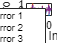

figure;
plot([errors,mean(errors,2)]);
xlabel('Location Index');
ylabel('Error');
legend("AOD Error 1","AOD Error 2","AOD Error 3","Mean AOD Error");